# Examples of how to use `solveSGEadySliceAdaptive` to solve the SG Eady slice equations

In this MATLAB live script, we show how to implement the adaptive time-stepping method described in *A new implementation of the geometric method for solving the Eady slice equations, *Egan *et. al., *(2022) for solving the **S**emi-**G**eostrophic (SG) Eady slice equations with periodic boundary conditions in the horizontal direction using the MATLAB function `solveSGEadySliceAdaptive.`

## 1. Background on the semi-geostrophic Eady slice equations 

The SG Eady slice equations model large scale atmospheric flows and frontogenesis. The are posed on a $$2$$-dimensional domain $$\Omega=[-L,L]\times [-H/2,H/2]$$ that represents a vertical slice through the atmosphere at a fixed latitude. Here, $$H$$ and $$L$$ are vertical and horizontal length scales. The equations themselves are given by


$$D_t v     + f u_1 = -\frac{gsx_2}{\theta_0},\\
		D_t\theta + s v   = 0,\\
		\nabla \cdot u    = 0,\\
		v = \frac{1}{f}\partial_1\phi,\\
		\theta=\frac{\theta_0}{g}\partial_2\phi.$$


When applied to the atmosphere, $$u=(u_1,u_2)$$ is the in-slice Eulerian fluid velocity, $$v$$ is the out-of-slice (or *meridional*) velocity, $$\theta$$ is the potential temperature, $$\phi$$ is the geopotential, $$f$$ is the Coriolis parameter, $$g$$ is the acceleration due to gravity, $$\theta_0$$ is a constant reference potential temperature, $$s<0$$ is a constant latitudinal temperature gradient, $$\nabla = (\partial_1,\partial_2)^T$$ is the in-slice gradient operator, and $$D_t:=\partial_t+u\cdot\nabla$$ is the in-slice material derivative operator. The two coordinates of an in-slice position vector $$\mathbf{x}=(x_1,x_2)\in\Omega$$ represent longitude and altitude, respectively.

The geometric method is a Lagrangian discretisation of the SG Eady slice equations, where the PDE given above is approximated by a particle system. Define the modified geopotential $$P:\Omega\to \mathbb{R}$$ by


$$P(\mathbf{x},t)=\frac{1}{2}x_1^2+\frac{1}{f^2}\phi(\mathbf{x},t).$$


Using the final two equations of the above PDE, we obtain the relation

$\nabla P(\mathbf{x},t)= 
\left(
\frac{1}{f}v(\mathbf{x},t)+x_1
,\,
\frac{g}{f^2\theta_0} \theta(\mathbf{x},t)
\right)$.

The SG Eady slice equations  then become


$$
			\left(\partial_t+\mathbf{u}\cdot\nabla\right)\nabla P= J\big(\text{id}_{\mathbb{x}}-\left(\nabla P\cdot\mathbf{e}_1\right)\mathbf{e}_1\big),\\
			\nabla\cdot \mathbf{u} = 0,$$


where $$\text{id}_{\mathbf{x}}(\mathbf{x},t)=\mathbf{x}$$, $$\mathbf{e}_1:=(1,0)$$ and $J$ is the $2\times 2$ skew-symetric matrix with zeros on the diagonal and $J_{12}=-\frac{gs}{f\theta_0}
	
$.

The *geometric method* is a Lagrangian discretisation of the above PDE for $$P$$, where the PDE is approximated by an ODE.

### 1.1. The geometric method

The ODE system solved in the geometric method is given by


$$	\dot{\mathbf{z}}_i=J\big(\mathbf{c}_i(\mathbf{z})-\left(\mathbf{z}_i\cdot \mathbf{e}_1\right)\mathbf{e}_1\big),\\
	\mathbf{z}_i(0)=\bar{\mathbf{z}}_{i},$$


for all $$i\in\{1,\ldots,n\}$$, for the *seeds *$\mathbf{z}=(\mathbf{z}_1,\ldots,\mathbf{z}_n):[0,T]\to\mathbb{R}^{2n}$. Here, $J$ is the $2\times 2$ skew-symetric matrix with zeros on the diagonal and $J_{12}=-\frac{gs}{f\theta_0}
	
$, $\bar{\mathbf{z}}=(\bar{\mathbf{z}}_1,\ldots,\bar{\mathbf{z}}_n)$ denotes the initial seed positions, and $$\mathbf{e}_1:=(1,0)$$.  The function $\mathbf{c}=(\mathbf{c}_1,\ldots,\mathbf{c}_n):\mathbb{R}^{2n}\to\mathbb{R}^{2n}$ is defined via a **S**emi-**D**iscrete **O**ptimal **T**ransport (SDOT) problem, as we now describe. 

Fix a set of *target masses* $\mathbf{m}=(m_1,\ldots,m_n)\in\mathbb{R}^n$, which sum to the area of $\Omega$. Define the periodic distance between $$\mathbf{x}, \mathbf{y} \in\mathbb{R}^2$$ as

		
$$|\mathbf{x}-\mathbf{y}|_{\mathrm{per}}:=\min_{\mathbf{k}\in K}|\mathbf{x}-\mathbf{y}-\mathbf{k}|,$$


where 

		
$$K:=\left\{2Lk\mathbf{e}_1\,\vert\, k\in\mathbb{Z}\right\}.$$


This distance accounts for periodicity in the horizontal direction. For seeds $\mathbf{z}=(\mathbf{z}_1,\ldots,\mathbf{z}_n)\in\mathbb{R}^{2n}$ and weights $\mathbf{w}=(w_1,\ldots,w_n)$, we define the collection of convex polygons $C_{1,\mathrm{per}}(\mathbf{z},\mathbf{w}),\, C_{2,\mathrm{per}}(\mathbf{z},\mathbf{w}),\ldots,C_{n,\mathrm{per}}(\mathbf{z},\mathbf{w})$ by 


$$C_{i,\mathrm{per}}(\mathbf{z},\mathbf{w})= \left\{ x \in \Omega : | \mathbf{z}-\mathbf{z}_i |_{\mathrm{per}}^2-w_i \le | \mathbf{z} -\mathbf{z}_j-\mathbf{k} |__{\mathrm{per}}^2-w_j \; \forall \, j \in \{1,\ldots,N\} \, \mathbf{k}\in K\right\}.$$


We denote by $\mathbf{w}_*(\mathbf{z})$ the weight vector such that

$\mathrm{Area}\big(C_{i,\mathrm{per}}(\mathbf{z},\mathbf{w}_*(\mathbf{z}))\big)=m_i\quad \forall i\in\{1,\ldots,n\}$.

This weight vector is unique up to the addition of constants, and it is found by solving an SDOT problem. We call it an optimal weight vector. The map $\mathbf{c}=(\mathbf{c}_1,\ldots,\mathbf{c}_n)$ is then defined by

$\displaystyle{\mathbf{c}_i(\mathbf{z})=\frac{1}{m_i}\int_{C_{i,\mathrm{per}}(\mathbf{z},\mathbf{w}_*(\mathbf{z}))}\mathbf{x}\mathrm{d}\mathbf{x}}\quad \forall i\in\{1,\ldots,n\}$.

That is, $\mathbf{c}_i$ is the centroid of the polygon $C_{i,\mathrm{per}}(\mathbf{z},\mathbf{w}_*(\mathbf{z}))$.

## 2. Example with manually generated initial condition

First we give a simple example with a manualy generated initial condition.

We define the physical parameters of the problem.

g   = 10;     % acceleration due to gravity
s   = -3e-6;  % latitudinal temperature gradient
f   = 1e-4;   % coriolis parameter
th0 = 3e+2;   % reference potential temperature
L   = 1e+6;   % half-domain length
H   = 1e+4;   % domain height (will be redefined to maximise growth rate of the perturbation)
N   = 5e-3;   % bouyancy frequency (needed to calculate the total geostrophic energy)

Next we define the fluid domain and specify the periodicity of the boundary conditions as follows:

perL = true;            % specifies periodicity in longitudinal direction
perV = false;           % specifies periodicity in vertical

Recall that the ODE for $$\mathbf{z}$
$ is defined via a semi-dicrete optimal transport problem, which has a fixed set of target masses $$\mathbf{m}$$. To set up the ODE, we therefore define these target masses.

n  = 100;                                          % number of seeds
M  = (2*L*H/n).*ones(n,1);                         % vector of cell masses

We then define the initial condition for the ODE.

Z0 = rand(n,2)*[2*L,0;0,H] - [L,H/2];  % array of initial seed positions

`Z0` are correspond to the initial seed positions $$\bar{\mathbf{z}}=(\bar{\mathbf{z}}_1,\ldots,\bar\mathbf{z}_n)$$ in the ODE, and they are stored in an $$n\times 2$$ array, where $$n$$ is the number of seeds. Finally, we define the simulation parameters.

T   = 100;  % final time
h   = 1;    % default time step size
eta = 1;    % percentage mass tolerance for optimal transport solver
K   = 10;   % integer such that data is recorded at every K-th time point

We solve the ODE for $\mathbf{z}$ as follows:

[Z,w,t,tolerances,halvings,runTime] = solveSGEadySliceAdaptive(g,s,f,th0,L,H,Z0,M,T,h,K,eta);

The number of steps, say `num_steps`, taken by the solver to reach the final time $$L$$ is determined by the adaptive time-stepping scheme. Let's find the smallest time-step that was chosen by the scheme.

hlv = max(halvings);
smallest_time_step = h/2^hlv

smallest_time_step = 1

The geometric method is structure preserving: solutions of the discretised equations give rise to mass-preserving flows in the fluid domain, and they conserve the total geostrophic energy. We now check that both of these properties hold for our numerical solution. The sense in which numerical solutions give rise to mass-preserving flows in the fluid domain is that the mass of each Laguerre cell is conserved over time. The output `tolerances` is a `num_steps`$$\times\, 1$$ array containing the percentage cell-area tolerances achieved in the semi-discrete optimal transport problem at each recorded step of the simulation. Let's check that they are all below the desired tolerance `eta`.

if max(tolerances)<=eta
    disp('Cell areas are conserved up to the specified tolerance.')
else
    disp('Cell areas are not conserved up to the specified tolerance.')
end

Cell areas are conserved up to the specified tolerance.


To check the conservation of the total geostrophic energy, we calculate the total energy $$E(t)$$ at each recorded time step using the MATLAB function `getRMSvMaxvEnergy`, and then compute the relative error as

$$$\mathcal{E}_n(t):=\frac{\bar{E}_n-E_n(t)}{\bar{E}_n}$$$,

 where $$E_n(t)$$ is the total geostrophic energy at time $$t$$ calculated from the numerical solutions and $$\bar{E}_n$ $is the temporal mean of this quantity.

[maxv,totalEnergy,energyConservationErrors] = getMaxvEnergy(f,L,H,N,perL,perV,t,Z,w);
maxRelError = num2str(max(energyConservationErrors));
disp(['Maximum relative error for the conservation of the total geostrophic energy is ',maxRelError])

Maximum relative error for the conservation of the total geostrophic energy is 5.1763e-08


## 3. Examples with normal mode initial conditions

The SG Eady slice equations admit a steady shear flow with


$$ (u_1,v,u_2,\theta,\phi)(x)=
 \left(\bar{u}_1(x_2),0,0, \frac{N^2 \theta_0}{g}\left(x_2+\frac{H}{2}\right),
\frac{N^2}{2}\left(x_2+\frac{H}{2}\right)^2 \right).$$


where,


$$\bar{u}_1(x_2)=-\frac{gsx_2}{f\theta_0}.$$


The corresponding modified geopotential $$\bar{P}$$ has gradient

$$\nabla \bar{P}(x)
= 
\left(
x_1,\, \frac{N^2}{f^2} \left( x_2 + \frac H2 \right)\right)
\end{array}\right)$.$.

When the Burger number $\mathrm{Bu}=\frac{NH}{fL}$ is less than a critical value, this steady state has unstable normal modes. Otherwise, all normal modes are stable. The critical Burger number is given by

$$\mathrm{Bu}_{\mathrm{crit}}=\frac{2\kappa_{\mathrm{crit}}}{\pi}$$,

where $$\kappa_{\mathrm{crit}}$$ is the smallest positive root of the equation

$(\kappa - \tanh \kappa)(\coth \kappa - \kappa)=0$.

We now give examples in both the unstable and stable paramter regimes.

### **3.1. Unstable normal mode perturbation**

First we give an example in which the parameter regime is automatically set so that it admits an unstable normal mode with the fastest possible growth rate.

We start by defining the dimensional parameters...

g   = 10;     % acceleration due to gravity
s   = -3e-6;  % latitudinal temperature gradient
f   = 1e-4;   % coriolis parameter
th0 = 3e+2;   % reference potential temperature
L   = 1e+6;   % half-domain length
H   = nan;    % domain height (will be redefined to maximise growth rate of the perturbation)
N   = 5e-3;   % bouyancy frequency
a   = -7.5;   % amplitude of perturbation

... and the simulation parameters.

numCols = 6;    % desired number of columns of seeds
T       = 100;  % final time
h       = 1;    % default time step size
K       = 10;   % integer such that data is recorded at every K-th time point
eta     = 1;    % percentage mass tolerance for optimal transport solver

We now generate our initial condition using the function `getICForSteadyShearPerturbation` with the chosen perturbation specified by the string `perturbation`.

perturbation = 'unstable'; % choose unstable normal mode from Williams (1967)
[Z0,M,H] = getICForSteadyShearPerturbation(perturbation,g,s,f,th0,L,H,N,a,numCols);

Here `Z0` are the initial seed positions, `M` is the mass vector, and `H` is the domain height that, given the other physical paramteres, is set so that the parameter regime permits the fastest growning unstable normal mode.

Finally, we solve the ODE and check the cell-mass conservation and energy conservation.

% Solve the ODE
[Z,w,t,tolerances,halvings,runTime] = solveSGEadySliceAdaptive(g,s,f,th0,L,H,Z0,M,T,h,K,eta);

% Check mass conservation
if max(tolerances)<=eta
    disp('Cell areas are conserved up to the specified tolerance.')
else
    disp('Cell areas are not conserved up to the specified tolerance.')
end

Cell areas are conserved up to the specified tolerance.



% Check energy conservation
[maxv,totalEnergy,energyConservationErrors] = getMaxvEnergy(f,L,H,N,perL,perV,t,Z,w);
maxRelError = num2str(max(energyConservationErrors));
disp(['Maximum relative error for the conservation of the total geostrophic energy is ',maxRelError])

Maximum relative error for the conservation of the total geostrophic energy is 7.8394e-05


### **3.2. Stable normal mode perturbation.**

In this example, we choose physical parameters in the stable regime and generate a discrete initial condition corresponding to a stable normal mode perturbation of the steady shear flow.

% Choose perturbation
perturbation = 'stable'; % choose stable normal mode

% Dimensional parameters
g   = 10;     % acceleration due to gravity
s   = -3e-6;  % latitudinal temperature gradient
f   = 1e-4;   % coriolis parameter
th0 = 3e+2;   % reference potential temperature
L   = 1e+6;   % half-domain length
H   = nan;   % domain height (will be redefined to set parameter regime as stable)
N   = 5e-3;   % bouyancy frequency
a   = -7.5;   % amplitude of perturbation

% Simulation parameters
numCols = 6;    % desired number of columns of seeds
T       = 100;  % final time
h       = 1;    % default time step size
K       = 10;   % integer such that data is recorded at every K-th time point
eta     = 1;    % percentage mass tolerance for optimal transport solver

% Get initial seeds, masses and domain height
[Z0,M,H] = getICForSteadyShearPerturbation(perturbation,g,s,f,th0,L,H,N,a,numCols);    

Note that there are multiple seeds that are aligned perpendicular to the boundary of $$\Omega$$. This is demonstrated in the following scatter plot.

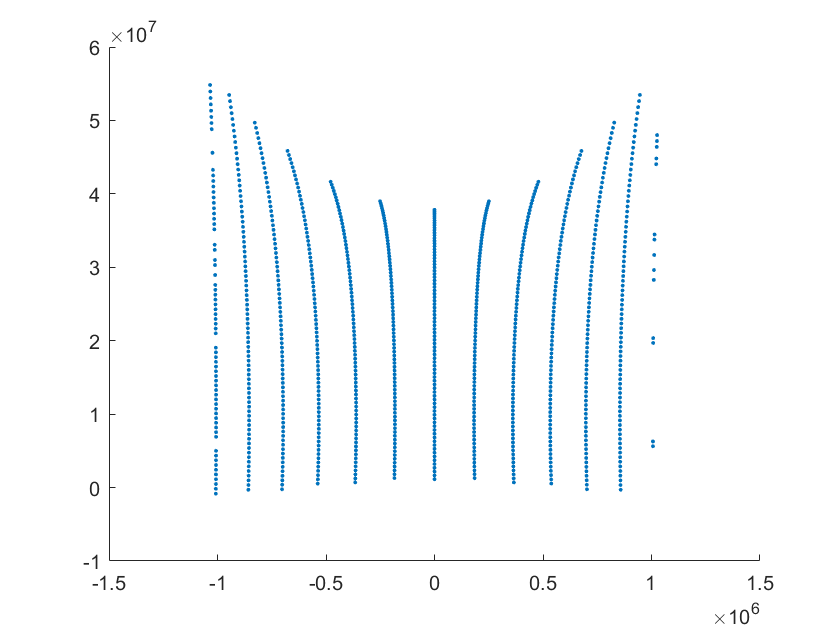

scatter(Z0(:,1),Z0(:,2),4,'filled') % scatter plot of initial seeds

This means that cells with zero area are generated by the weights returned by the MATLAB function `getDefaultWeightGuess`.

w0 = getDefaultWeightGuess(bx,Z0,perL,perV);
areas = mexPDall_2d(bx,Z0,w0,perL,perV);
areaThreshold  = max([(1e-14)*2*L*H/numel(areas),1e-14]);
if min(areas)<=areaThreshold
    disp('Cell of zero area is generated by default weight guess.')
end

Cell of zero area is generated by default weight guess.


When `initialiseDampedNewton2d` is called at the first step of `solveSGEadySliceAdaptive` (line `96`), the `if` loop (line `107`) is therefore entered. Here, we randomly perturb the seeds to avoid having seeds aligned perpendicular to the boundary of $$\Omega$$. The MATLAB function `getDefaultWeightGuess` is then applied to the perturbed seeds `ZNew`, and optimal weights `wNew `for these perturbed seeds are computed. The weights `wNew` are tested as an initial guess for the unperturbed seeds `Z0`. The size of the perturbation is iteratively decreased until a good weight guess `w0 `for the unperturbed seeds `Z0 `is found.

% Solve ODE
[Z,w,t,tolerances,halvings,runTime] = solveSGEadySliceAdaptive(g,s,f,th0,L,H,Z0,M,T,h,K,eta);

We check the cell-mass conservation and energy conservation.

% Check mass conservation
if max(tolerances)<=eta
    disp('Cell areas are conserved up to the specified tolerance.')
else
    disp('Cell areas are not conserved up to the specified tolerance.')
end

Cell areas are conserved up to the specified tolerance.



% Check energy conservation
[maxv,totalEnergy,energyConservationErrors] = getMaxvEnergy(f,L,H,N,perL,perV,t,Z,w);
maxRelError = num2str(max(energyConservationErrors));
disp(['Maximum relative error for the conservation of the total geostrophic energy is ',maxRelError])

Maximum relative error for the conservation of the total geostrophic energy is 1.0853e-05


## **4. Examples of other initial conditions from the literature**

We now give two examples of initial conditions used in the literature. Both are unstable perturbations of the steady shear flow stated above.

### **4.1. Unstable perturbation from Cullen (2007)**

%Choice of perturbation
perturbation = 'Cullen'; % choose unstable perturbation defined in Cullen (2007)

%Dimensional parameters
g   = 10;     % acceleration due to gravity
s   = -3e-6;  % latitudinal temperature gradient
f   = 1e-4;   % coriolis parameter
th0 = 3e+2;   % reference potential temperature
L   = 1e+6;   % half-domain length
H   = 1e+4;   % domain height (will be redefined to maximise growth rate of the perturbation)
N   = 5e-3;   % bouyancy frequency
a   = 0.25;      % amplitude of perturbation

%Simulation parameters
numCols = 7;  % desired number of columns of seeds
T       = 100;  % final time
h       = 1;    % default time step size
K       = 10;   % integer such that data is recorded at every K-th time point
eta     = 1;    % percentage mass tolerance for optimal transport solver

% Get initial seeds, masses and domain height
[Z0,M,H] = getICForSteadyShearPerturbation(perturbation,g,s,f,th0,L,H,N,a,numCols);

% Solve ODE
[Z,w,t,tolerances,halvings,runTime] = solveSGEadySliceAdaptive(g,s,f,th0,L,H,Z0,M,T,h,K,eta);

### 4.2. Unstable perturbation from Visram *et. al. *(2014)

% Unstable perturbation and parameters defined in Visram et. al. (2014)

%Choice of perturbation
perturbation = 'Visram'; % choose unstable perturbation defined in Visram et. al. (2014)

%Dimensional parameters
g   = 10;     % acceleration due to gravity
s   = -3e-6;  % latitudinal temperature gradient
f   = 1e-4;   % coriolis parameter
th0 = 3e+2;   % reference potential temperature
L   = 1e+6;   % half-domain length
H   = 1e+4;   % domain height (will be redefined to maximise growth rate of the perturbation)
N   = 5e-3;   % bouyancy frequency
a   = -7.5;      % amplitude of perturbation

%Simulation parameters
numCols = 6;  % desired number of columns of seeds
T       = 100;  % final time
h       = 1;    % default time step size
K       = 10;   % integer such that data is recorded at every K-th time point
eta     = 1;    % percentage mass tolerance for optimal transport solver

% Get initial seeds, masses and domain height
[Z0,M,H] = getICForSteadyShearPerturbation(perturbation,g,s,f,th0,L,H,N,a,numCols);

% Solve ODE
[Z,w,t,tolerances,halvings,runTime] = solveSGEadySliceAdaptive(g,s,f,th0,L,H,Z0,M,T,h,K,eta);